This aims to explore he different vairables which we can use in a mediation analysis.

Also run single level mediation, however, keep in mind that is the effects are inflated as the grouping of the data is not provided to the data. Check also the multilevel mediation (started in this livescript) but provided in the multilevel mediation livescript.

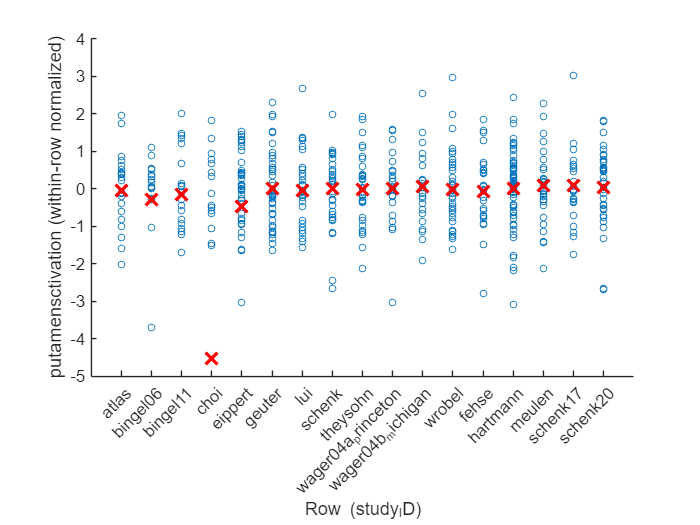

%This figure shows each studies putamen activation (placebo - control)
%normalized distributions. the red X -s represent hte original values
%average.
%each study has relavitely similar average value and after normalization
%the distribution is the same
%there seems to be no activation/deactivation in the putamen
%NOTE: the direction can be changed in such a way that higher value means
%higher placebo effect, however, this is something which depends on the
%region
plotRowValuesWithMeans(df,"putamensctivation","study_ID",false,'showoriginalmean',true)

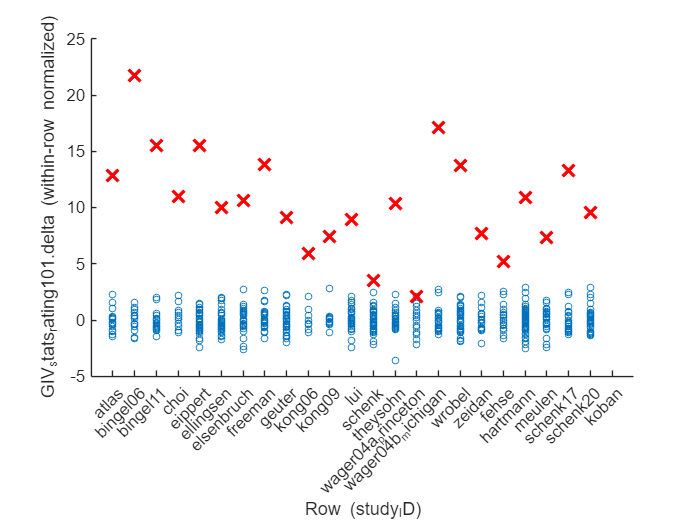

%the similar plot for the ratings. The average rating difference
%(control-placebo--> higher means higher placebo effect)
plotRowValuesWithMeans(df,"GIV_stats_rating101.delta","study_ID",true,'showoriginalmean',true)

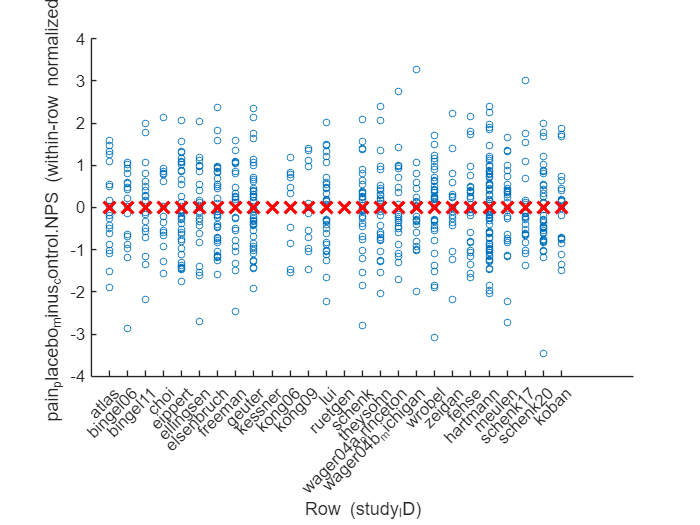

plotRowValuesWithMeans(df,"pain_placebo_minus_control.NPS","study_ID",false,'showoriginalmean',false)

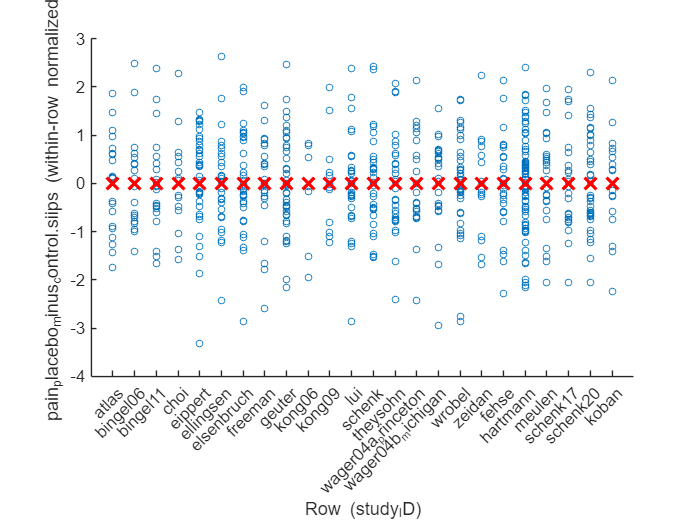

plotRowValuesWithMeans(df,"pain_placebo_minus_control.siips","study_ID",false,'showoriginalmean',false)

plotRowValuesWithMeans(df,"anticip_placebo_minus_control.nps","study_ID",false,'showoriginalmean',true)
plotRowValuesWithMeans(df,"anticip_placebo_minus_control.siips","study_ID",false,'showoriginalmean',true)

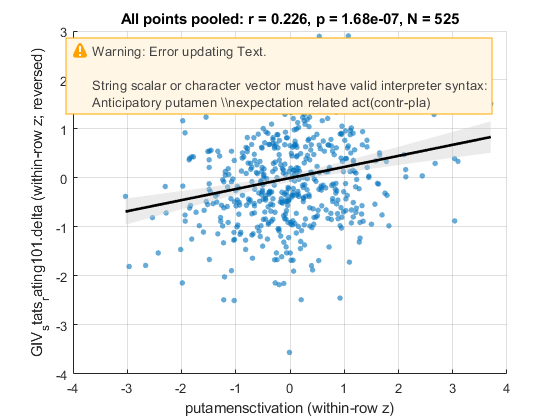

alloutputs = struct with fields:
         r: 0.2259
         p: 1.6818e-07
         N: 525
       mdl: [1×1 LinearModel]
         X: [525×1 double]
         Y: [525×1 double]
      covs: [525×2 double]
         M: [525×1 double]
    rowIdx: [525×1 double]
    labels: [0×1 string]



%this scatter plot is very important to understgand in more detail:
%Y axis, behavor:becuase of the original forest plot, the ratings represent
%plcebo-control--> I have to reverse it, so higher value corresponds to higher placebo effect
% X axis, brain/putamen/ activation: the original activation was placebo-control focus, I guess beacuse that would mean more activation
% in the placebo, however, this depends on the region of interest. While this holds for the DLPFC,ACC, the reversed should be suggested for
% S1,S2,pIns,... .So a control-placebo would mean higher placebo effect (higher reduction in signal in the placebo condition).
% 
alloutputs = corrScatterAllPointsWithCI(df,"putamensctivation","GIV_stats_rating101.delta",'marker',"pain_placebo_minus_control.NPS","cov",true)

% [paths, stats] = mediation(X, Y, M, 'plots', 'verbose', 'robust',
% 'boot'); 'plots',
%'covs',alloutputs.covs,
[pathsnps, statsnps] = mediation(alloutputs.X, alloutputs.Y, alloutputs.M, 'verbose','robust', 'boot',...
     'names', {'Putant(pl-ctr)' 'Behav(pl-ctr)' 'NPSpain(pl-ctr)'})

Note: Turning off iteration limit warning for robustfit.
Mediation analysis

Observations: 525, Replications:   1
Predictor (X): Putant(pl-ctr), Outcome (Y): Behav(pl-ctr): Mediator (M): NPSpain(pl-ctr)

Covariates: No

Single-level analysis.
Options:
	Plots: No
	Bootstrap: Yes
	Robust: Yes
	Logistic(Y): No
	Bootstrap or sign perm samples: 1000

Bootstrapping:  Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples  Done adding in  20 s 
Done in  26 (s) 
 Done.

________________________________________
Final bootstrap samples: 5867
Average p-value tolerance (average max alpha): 0.0060

Single-level model
	a	b	c'	c	ab	
Coeff	0.17	0.24	0.17	0.21	0.04	
STE	0.05	0.04	0.04	0.04	0.01	
t (~N)	3.77	5.36	3.71	4.84	2.93	
Z	3.20	3.63	3.61	3.67	3.30	
p	0.0014	0.0003	0.0003	0.0002	0.0010	

________________________________________
Total time:  26 s


pathsnps =     0.1733    0.2399    0.1643    0.2133    0.0416


statsnps = struct with fields:
           names: {'a'  'b'  'c''  'c'  'ab'}
            mean: [0.1733 0.2404 0.1650 0.2129 0.0419]
             ste: [0.0460 0.0449 0.0445 0.0440 0.0143]
               p: [0.0014 2.8347e-04 3.0462e-04 2.4632e-04 9.5189e-04]
          vnames: {'Putant(pl-ctr)'  'Behav(pl-ctr)'  'NPSpain(pl-ctr)'}
     bootsamples: 5867
     alphaaccept: 0.0060
               z: [3.2020 3.6300 3.6113 3.6661 3.3044]
     biascorrect: 'BCa bias corrected'
          residm: {[525×1 double]}
          residy: {[525×1 double]}
         residy2: {[525×1 double]}
           paths: [0.1733 0.2399 0.1643 0.2133 0.0416]
               w: [525×525 double]
        stdpaths: [0 0 0 0 0]
          abetas: {[2×1 double]}
          bbetas: {[2×1 double]}
         cpbetas: {[2×1 double]}
          cbetas: {[2×1 double]}
    inputOptions: [1×1 struct]
    analysisname: 'Single-level model'


Mediation analysis

Observations:  17, Replications:  17
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 017 Done.
Bootstrapping 10000 samples... Min p-value is 0.145200. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 


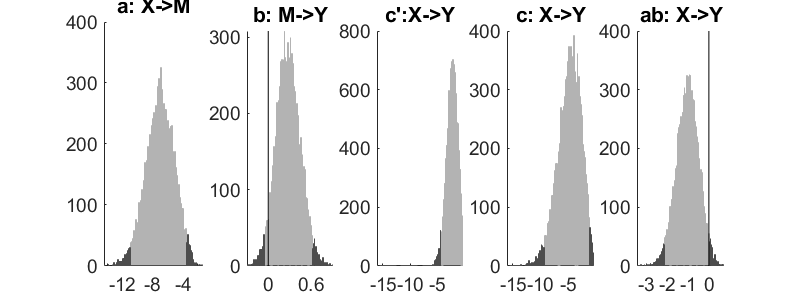

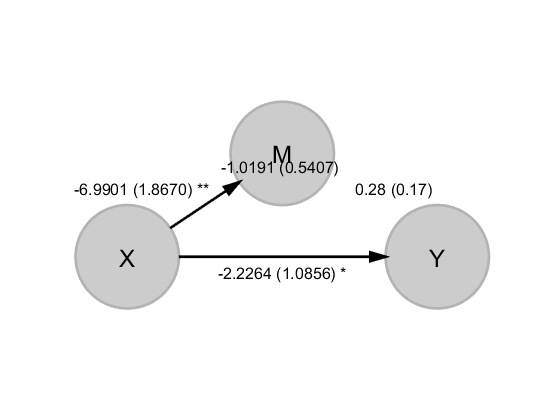

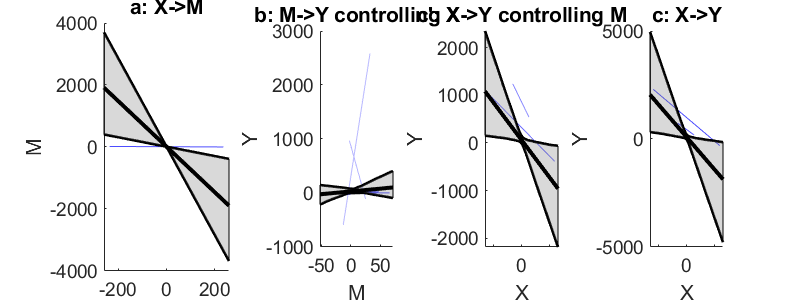

No second-level covariates; omitting 2nd level scatterplots.


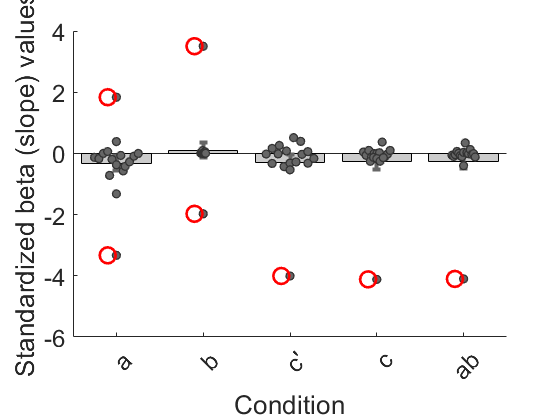

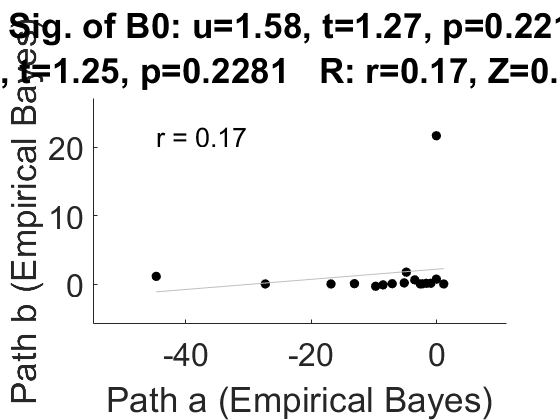


________________________________________
Average p-value tolerance (average max alpha): 0.1742

Multi-level model
	a	b	c'	c	ab	
Coeff	-6.99	0.28	-2.23	-4.75	-1.02	
STE	1.87	0.17	1.09	2.12	0.54	
t (~N)	-3.74	1.63	-2.05	-2.24	-1.88	
Z	-3.29	1.76	-1.98	-2.20	-1.80	
p	0.0010	0.0789	0.0472	0.0280	0.0724	

________________________________________
Total time:   3 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...

moderatorpath= "pain_placebo_minus_control.NPS";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = df.putamensctivation{k,1}(:);
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
%         M{k} = (M{
% k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths, stats] = mediation(X, M, Y, ...
    'boot', 'verbose','plots',... %'plots', 
    'bootsamples', 10000);

% Multilevel options
% 'hierarchical'    multi-level model with weighing based on 1st level variance
% 'summarystats'    use summary-statistics approach with multi-level data;
% no weighting

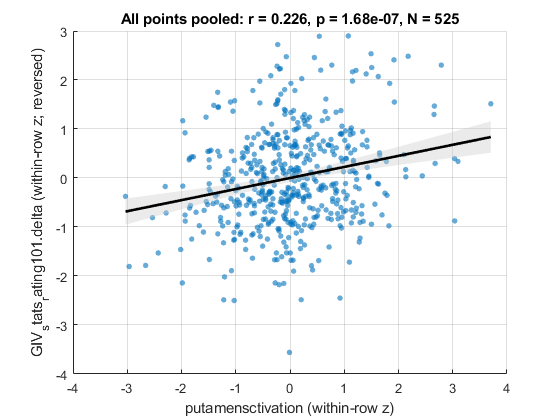

alloutputs = struct with fields:
         r: 0.2259
         p: 1.6818e-07
         N: 525
       mdl: [1×1 LinearModel]
         X: [525×1 double]
         Y: [525×1 double]
         M: [525×1 double]
    rowIdx: [525×1 double]
    labels: [0×1 string]




alloutputs = corrScatterAllPointsWithCI(df,"putamensctivation","GIV_stats_rating101.delta",'marker',"pain_placebo_minus_control.siips")

Note: Turning off iteration limit warning for robustfit.
Mediation analysis

Observations: 525, Replications:   1
Predictor (X): Putant(pl-ctr), Outcome (Y): Behav(pl-ctr): Mediator (M): SIIPSpain(pl-ctr)

Covariates: No

Single-level analysis.
Options:
	Plots: Yes
	Bootstrap: Yes
	Robust: Yes
	Logistic(Y): No
	Bootstrap or sign perm samples: 1000

Bootstrapping:  Min p-value is 0.001000. Adding 4867 samples
  Adding 4867 samples  Done adding in  18 s 
Done in  25 (s) 


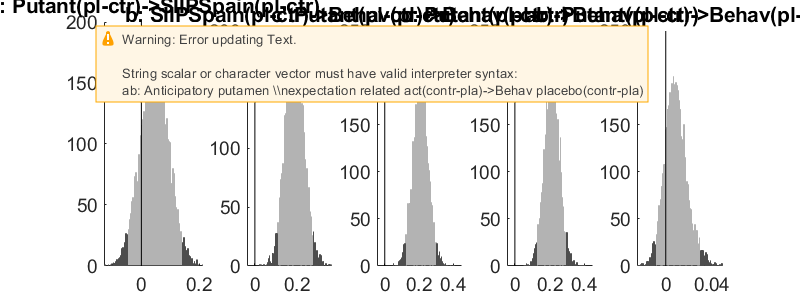

 Done.
Mediation scatterplots:
Replications:   1
Covariates controlled for in all regressions:   0 predictors
Additional mediators controlled for in outcome predictions:   1 predictors


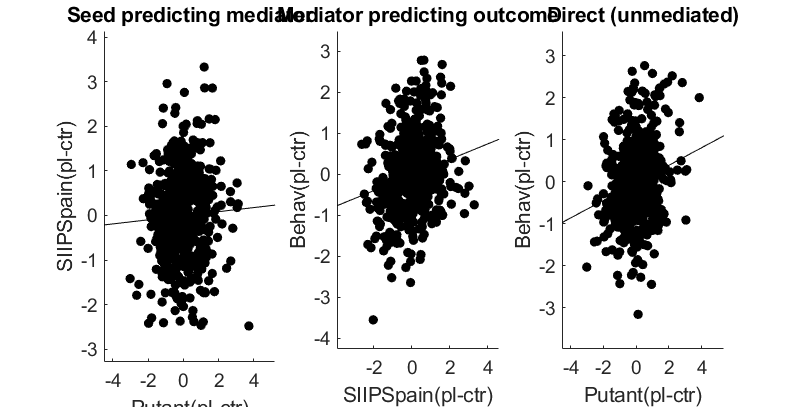

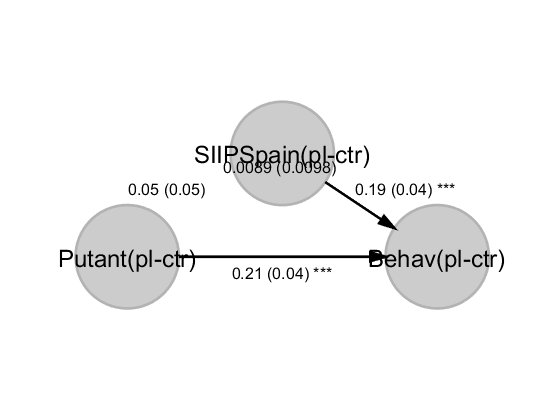


________________________________________
Final bootstrap samples: 5867
Average p-value tolerance (average max alpha): 0.0060

Single-level model
	a	b	c'	c	ab	
Coeff	0.05	0.19	0.21	0.21	0.01	
STE	0.05	0.04	0.04	0.04	0.01	
t (~N)	0.95	4.24	4.72	4.91	0.91	
Z	0.97	3.60	3.68	3.65	1.05	
p	0.3331	0.0003	0.0002	0.0003	0.2927	

________________________________________
Total time:  47 s


ans =     0.0458    0.1904    0.2093    0.2133    0.0087


mediation(alloutputs.X, alloutputs.Y, alloutputs.M,'plots', 'verbose','robust', 'boot',...
     'names', {'Putant(pl-ctr)' 'Behav(pl-ctr)' 'SIIPSpain(pl-ctr)'})

Mediation analysis

Observations:  17, Replications:  17
Predictor (X): X, Outcome (Y): Y: Mediator (M): M

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: No
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 017 Done.
Bootstrapping 10000 samples... Min p-value is 0.000100. Adding   0 samples
 Bootstrapping...Estimating variance components based on 10000 bootstrap samples
 Done in   0 s 


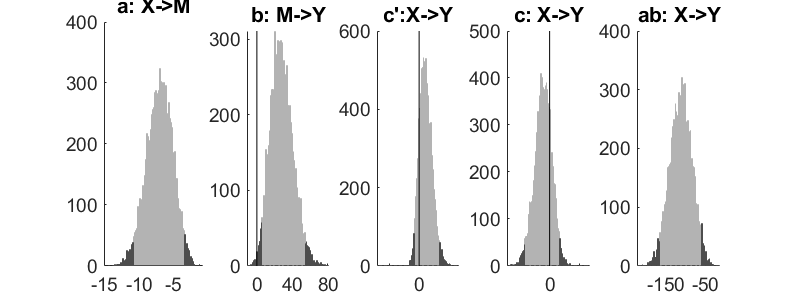

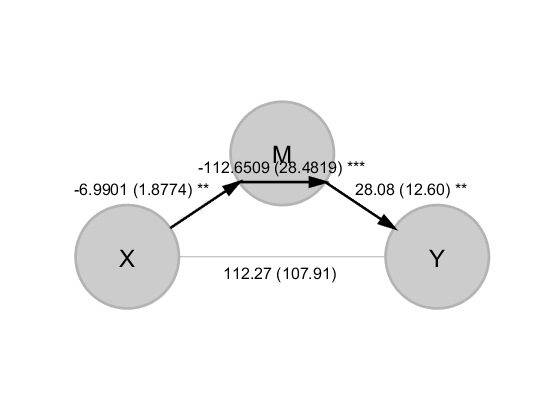

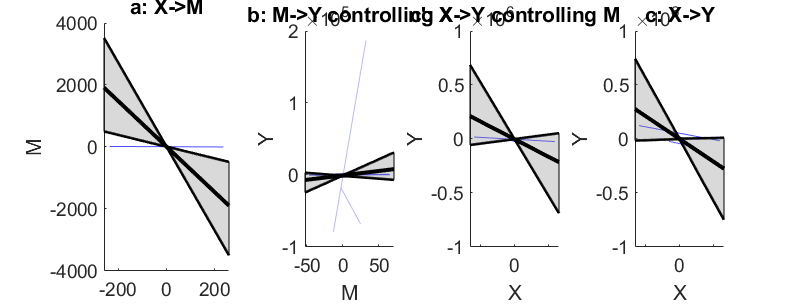

No second-level covariates; omitting 2nd level scatterplots.


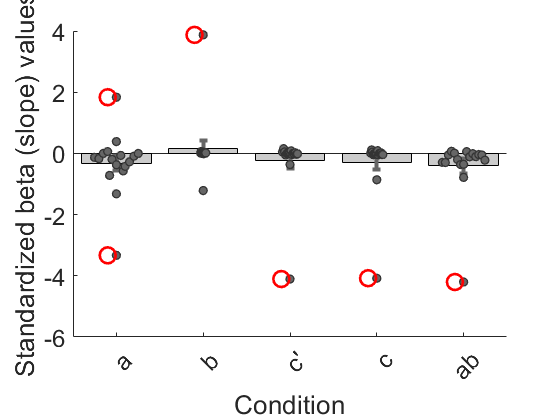

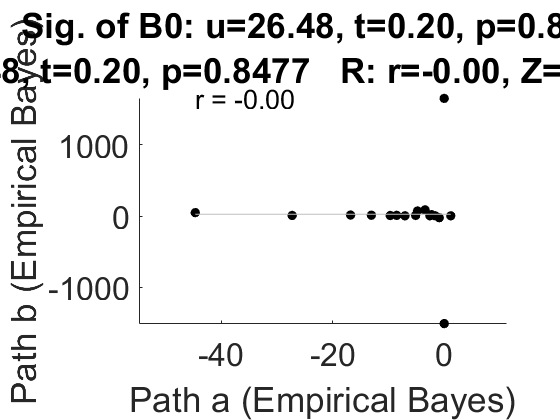


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-6.99	28.08	112.27	-104.79	-112.65	
STE	1.88	12.60	107.91	143.47	28.48	
t (~N)	-3.72	2.23	1.04	-0.73	-3.96	
Z	-3.26	3.22	1.32	-0.68	-3.47	
p	0.0011	0.0013	0.1862	0.4951	0.0005	

________________________________________
Total time:   3 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...

moderatorpath= "pain_placebo_minus_control.siips";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = df.putamensctivation{k,1}(:);
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
%         M{k} = (M{
% k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths, stats] = mediation(X, M, Y, ...
    'boot', 'verbose','plots',... %'plots', 
    'bootsamples', 10000);


%this part explore a bit more the correlation between putamen and the
%behavior analgesia 
%here we need the signficnat putamen mask for calculating the activation.
%take a look in the C:\Users\lenov\Documents\PICO\C_calculations\mygithubproject\anticipation_analysis\F_additionalanalysis\putamenrole.mlx file to understand how it was calucalated the signifmask
subjidpath = "anticip_placebo.sub_ID";
placeboratingpath = "anticip_placebo.rating101";

placeboratingpath = "anticip_placebo.rating101"

controlratingpath = "anticip_control.rating101";

controlratingpath = "anticip_control.rating101"

%note that there is a difference between this and the original, as the
%putamenactivation contains the Wager04princeton study, which is a
%withinsubj but only provided contrast images(also there are few NA values+
%the wager04bmichigan study only contains contrast ratings)

 for studyrank=1:height(df)
        if strcmp(df.study_design{studyrank,1},'within') && ~isempty(dfv_masked.anticip_control{studyrank,1})
            subjid = extractVectorFromPath(df, subjidpath, studyrank, false); % subjectid
            placeborating = extractVectorFromPath(df, placeboratingpath, studyrank, false);
            controlrating = extractVectorFromPath(df, controlratingpath, studyrank, false);
            putamenactinplacebo = mean(dfv_masked.anticip_placebo{studyrank,1}(:,signifmask),2);
            putamenactincontrol = mean(dfv_masked.anticip_control{studyrank,1}(:,signifmask),2);
            %normalized activation
            norm_putamenactinplacebo = (putamenactinplacebo - mean(putamenactinplacebo,'omitnan')) ./ std(putamenactinplacebo,'omitnan');   % z-score
            norm_putamenactincontrol = (putamenactincontrol - mean(putamenactincontrol,'omitnan')) ./ std(putamenactincontrol,'omitnan');   % z-score

            Tnew = table(subjid(:), placeborating(:), controlrating(:), putamenactinplacebo(:),putamenactincontrol(:),norm_putamenactinplacebo(:),norm_putamenactincontrol(:), ...
                'VariableNames', {'subjid','placeborating','controlrating','putamenactinplacebo','putamenactincontrol','norm_putamenactinplacebo','norm_putamenactincontrol'});
            if studyrank == 1
                Tall = Tnew;
            else
                Tall = [Tall; Tnew];   % vertical concatenation (adds rows)
            end

        end
 end

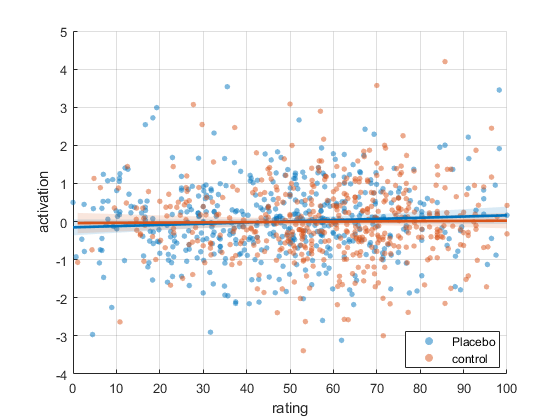

% T is your table with 5 columns
x1 = Tall{:,2}; y1 = Tall{:,6}; %placebo
x2 = Tall{:,3}; y2 = Tall{:,7}; %control

% keep only finite pairs
m1 = isfinite(x1) & isfinite(y1);
m2 = isfinite(x2) & isfinite(y2);
x1 = x1(m1); y1 = y1(m1);
x2 = x2(m2); y2 = y2(m2);

figure; hold on

% scatter (different colors)
scatter(x1,y1,18,'filled','MarkerFaceColor',[0 0.45 0.74],'MarkerFaceAlpha',0.5)
scatter(x2,y2,18,'filled','MarkerFaceColor',[0.85 0.33 0.10],'MarkerFaceAlpha',0.5)

% fit + 95% CI (mean response)
mdl1 = fitlm(x1,y1);
mdl2 = fitlm(x2,y2);

xg1 = linspace(min(x1),max(x1),200)';  [yhat1,ci1] = predict(mdl1,xg1,'Alpha',0.05);
xg2 = linspace(min(x2),max(x2),200)';  [yhat2,ci2] = predict(mdl2,xg2,'Alpha',0.05);

% CI bands
fill([xg1; flipud(xg1)], [ci1(:,1); flipud(ci1(:,2))], [0 0.45 0.74], ...
     'FaceAlpha',0.15,'EdgeColor','none');
fill([xg2; flipud(xg2)], [ci2(:,1); flipud(ci2(:,2))], [0.85 0.33 0.10], ...
     'FaceAlpha',0.15,'EdgeColor','none');

% trend lines
plot(xg1,yhat1,'-','Color',[0 0.45 0.74],'LineWidth',2)
plot(xg2,yhat2,'-','Color',[0.85 0.33 0.10],'LineWidth',2)

xlabel('rating'); ylabel('activation');
legend({'Placebo','control'},'Location','best')
grid on

% Inputs (each is Nsubj x 1):
% x1 = rating placebo,   x2 = rating control
% y1 = activation placebo, y2 = activation control
% subj = subject IDs (numeric/categorical/strings)
% T is your table with 5 columns
x1 = Tall{:,2}; y1 = Tall{:,6}; %placebo
x2 = Tall{:,3}; y2 = Tall{:,7}; %control

N = numel(Tall.subjid);

rating     = [x1(:); x2(:)];
activation = [y1(:); y2(:)];
condition  = [repmat("placebo",N,1); repmat("control",N,1)];
subj_long  = [Tall.subjid(:); Tall.subjid(:)];

Tlong = table(rating, activation, categorical(condition), categorical(subj_long), ...
    'VariableNames', {'rating','activation','condition','subj'});

% (optional) drop missing rows
Tlong = rmmissing(Tlong);

% Mixed model: rating ~ condition * activation + (1|subj)
lme = fitlme(Tlong, 'rating ~ condition*activation + (1|subj)');
disp(lme)

Linear mixed-effects model fit by ML

Model information:
    Number of observations             948
    Fixed effects coefficients           4
    Random effects coefficients        458
    Covariance parameters                2

Formula:
    rating ~ 1 + activation*condition + (1 | subj)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    8240.3    8269.4    -4114.1          8228.3  

Fixed effects coefficients (95% CIs):
    Name                                    Estimate    SE         tStat      DF     pValue      Lower   
    {'(Intercept)'                 }         58.278     0.99492     58.576    944           0      56.326
    {'activation'                  }         1.4295     0.78324     1.8251    944    0.068303    -0.10761
    {'condition_placebo'           }        -10.837     0.83212    -13.024    944           0      -12.47
    {'activation:condition_placebo'}   

To assign to or create a variable in a table, the number of rows must match the height of the table.

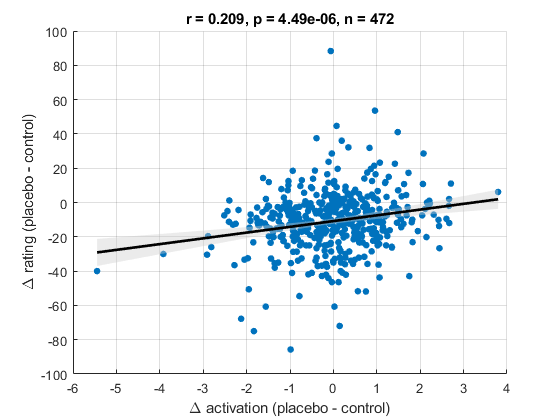

% x1=rating placebo, x2=rating control
% y1=activation placebo, y2=activation control

dRating = x1(:) - x2(:);      % placebo - control
dActiv  = y1(:) - y2(:);      % placebo - control

% remove missing pairs
m = isfinite(dRating) & isfinite(dActiv);
dRating = dRating(m);
dActiv  = dActiv(m);

% correlation
[r,p] = corr(dRating, dActiv, 'Type','Pearson');

% optional plot
figure; hold on
scatter(dActiv, dRating, 25, 'filled')
mdl = fitlm(dActiv, dRating);
xg = linspace(min(dActiv), max(dActiv), 200)';
[yhat, ci] = predict(mdl, xg, 'Alpha', 0.05);
fill([xg; flipud(xg)], [ci(:,1); flipud(ci(:,2))], [0.8 0.8 0.8], ...
     'EdgeColor','none','FaceAlpha',0.4);
plot(xg, yhat, 'k-', 'LineWidth', 2)
xlabel('\Delta activation (placebo - control)')
ylabel('\Delta rating (placebo - control)')
title(sprintf('r = %.3f, p = %.3g, n = %d', r, p, numel(dRating)))
grid on

function plotRowValuesWithMeans(df, valuePath, nameVarName, reverse,varargin)
        % Plot per-row vectors/values (normalized within row if vector) and mark means.
        %
        % valuePath examples:
        %   "putamensctivation"
        %   "GIV_stats_rating.delta"
        %
        % reverse: if true (or 1), multiply extracted values by -1 before normalization/plot
        
            p = inputParser;
        
            % Required arguments
            addRequired(p, 'valuePath', @isstring);
            addRequired(p, 'nameVarName', @isstring);
            % Optional arguments with default values
            %these are all the 34 subjects:
        %     allsubjid={7349, 7356, 7361, 7375, 7376,...
        %          7383, 7402, 7403, 7404,...
        %          7405, 7408, 7414, 7415,...
        %          7425, 7426, 7433, 7434,...
        %          7435, 7443, 7444, 7445,...
        %          7448, 7449, 7452, 7453,...
        %          7454, 7455, 7456, 7457,...
        %          7468, 7469, 7482, 7484, 7485};
        %     defpathtosubjdata='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        %     selectedcolumnvalue='200';
            
            addOptional(p, 'showoriginalmean', true, @islogical);
        %     addOptional(p, 'pathtosubjdata', defpathtosubjdata, @ischar);
        %     addOptional(p, 'SELECTEDCOLUMNS', selectedcolumnvalue, @ischar);
        %     
        % 
        %     % Parse inputs
            parse(p, valuePath,nameVarName, varargin{:});
        %     
        %     % Extract values
            showoriginalmean = p.Results.showoriginalmean;
        %     visualize = p.Results.visualization;
        %     pathtosubj = p.Results.pathtosubjdata;
        %     selectedcolumns = p.Results.SELECTEDCOLUMNS;
        
        if nargin < 4 || isempty(reverse)
            reverse = false;
        end
        reverse = logical(reverse);
        
        parts   = split(valuePath, ".");
        baseVar = parts(1);
        subField = "";
        if numel(parts) > 1
            subField = parts(2);   % one level: var.field
        end
        
        nR = height(df);
        
        x_all = [];
        y_all = [];
        x_mean = [];
        y_mean = [];
        tickLabels = {};
        k = 0;
        
        for r = 1:nR
            obj = df.(baseVar)(r);
            if iscell(obj), obj = obj{1}; end
        
            % Extract value(s)
            if subField ~= ""
                if istable(obj)
                    if ~ismember(subField, string(obj.Properties.VariableNames)), continue; end
                    v = obj.(subField);
                elseif isstruct(obj)
                    if ~isfield(obj, subField), continue; end
                    v = obj.(subField);
                else
                    continue
                end
            else
                v = obj;
            end
        
            if isempty(v), continue; end
        
            v = v(:);
        
            % Optional reversal
            if reverse
                v = -1 .* v;
            end
        
            % Normalize within row
            mu = mean(v);
            sd = std(v);
            if numel(v) < 2 || sd==0 || isnan(sd)
                vnorm = v - mu;           % scalar/constant: mean-center (scalar -> 0)
            else
                vnorm = (v - mu) ./ sd;   % z-score
            end
        
            k = k + 1;
            x_all  = [x_all;  repmat(k, numel(vnorm), 1)];
            y_all  = [y_all;  vnorm];
        
            x_mean(end+1,1) = k;
            if showoriginalmean
                y_mean(end+1,1) = mu;
            else
                y_mean(end+1,1) = mean(y_all,'omitnan');
            end
        
            nm = df.(nameVarName)(r);
            if iscell(nm), nm = nm{1}; end
            tickLabels{end+1} = string(nm);
        end
        
        figure; hold on
        plot(x_all, y_all, 'o', 'MarkerSize', 4)
        plot(x_mean, y_mean, 'rx', 'MarkerSize', 10, 'LineWidth', 2)
        
        ax = gca;
        ax.XTick = 1:k;
        ax.XTickLabel = tickLabels;
        ax.XTickLabelRotation = 45;
        
        xlabel("Row (" + nameVarName + ")")
        ylabel(valuePath + " (within-row normalized)")
end

function out = corrScatterAllPointsWithCI(df, xPath, yPath, varargin)
% Extract per-row vectors from xPath and yPath, z-normalize WITHIN EACH ROW,
% reverse ONLY y values (multiply by -1), then pool ALL individual points
% across rows for correlation + scatter + regression line with 95% CI.
%
% Example:
% out = corrScatterAllPointsWithCI(df,"putamensctivation","GIV_stats_rating101.delta","name");

p = inputParser;
        
            % Required arguments
            addRequired(p, "xPath", @isstring);
            addRequired(p, "yPath", @isstring);
            % Optional arguments with default values
            %these are all the 34 subjects:
        %     allsubjid={7349, 7356, 7361, 7375, 7376,...
        %          7383, 7402, 7403, 7404,...
        %          7405, 7408, 7414, 7415,...
        %          7425, 7426, 7433, 7434,...
        %          7435, 7443, 7444, 7445,...
        %          7448, 7449, 7452, 7453,...
        %          7454, 7455, 7456, 7457,...
        %          7468, 7469, 7482, 7484, 7485};
        %     defpathtosubjdata='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
        %     selectedcolumnvalue='200';
        addOptional(p, "marker", "", @isstring);
        addOptional(p, "covs", false, @islogical);
        %     addOptional(p, 'subjectids', allsubjid, @iscell);
        %     addOptional(p, 'visualization', 'no', @ischar);
        %     addOptional(p, 'pathtosubjdata', defpathtosubjdata, @ischar);
        %     addOptional(p, 'SELECTEDCOLUMNS', selectedcolumnvalue, @ischar);
        %     
        % 
        %     % Parse inputs
            parse(p, xPath,yPath, varargin{:});
        %     
        %     % Extract values
            marker = p.Results.marker;
            covariates= p.Results.covs;
        %     visualize = p.Results.visualization;
        %     pathtosubj = p.Results.pathtosubjdata;
        %     selectedcolumns = p.Results.SELECTEDCOLUMNS;



    xPath = string(xPath);
    yPath = string(yPath);
    
    nR = height(df);
    
    X = []; Y = []; rowIdxAll = []; labels = strings(0,1);
    M = [];
    Covar = [];
    %this ishardocded as it is the same always
    covvars1="pain_placebo_minus_control.male";
    covvars2="pain_placebo_minus_control.age";
    for rRow = 1:nR
        if strcmp(df.study_design{rRow,1},'within')
            vx = extractVectorFromPath(df, xPath, rRow, true); % reverse putamen
            vy = extractVectorFromPath(df, yPath, rRow, true);  % reverse rating
            
            
            if isempty(vx) || isempty(vy)
                continue
            end
        
            vx = vx(:); vy = vy(:);
        
            % require same length so we can pair points
    %         n = min(numel(vx), numel(vy));
    %         vx = vx(1:n);
    %         vy = vy(1:n);
        
            % drop NaN pairs
            good = isfinite(vx) & isfinite(vy);
            if any(isnan(vx(:))) || any(isnan(vy(:)))
                warning("there are NAN values!")
            end
            vx = vx(good);
            vy = vy(good);
            if isempty(vx), continue; end
            if strlength(marker) && length(vx)~=0
                vm=extractVectorFromPath(df, marker , rRow, true); %the marker is also reversed, so for placebo-control-->it will be 
                vm = vm(:);
                vm = vm(good);
                vm = zNormSafe(vm);
                
                M = [M; vm];
            end
            if covariates && length(vx)~=0
                cov = [extractVectorFromPath(df, covvars1, rRow, false) extractVectorFromPath(df, covvars2, rRow, false)];
                
                cov = cov(good,:);
                Covar = [Covar; cov];
            end

            % within-row z-score normalization (separately for x and y)
            vx = zNormSafe(vx);
            vy = zNormSafe(vy);
            
        
            X = [X; vx];
            Y = [Y; vy];
            
            rowIdxAll = [rowIdxAll; repmat(rRow, numel(vx), 1)];
        end

    end
    
    % correlation
    if numel(X) >= 3
        [r,p] = corr(X, Y, 'Type','Pearson');
    else
        r = NaN; p = NaN;
    end
    
    % regression + 95% CI for mean response
    mdl = fitlm(X, Y);
    xgrid = linspace(min(X), max(X), 200)';
    [yhat, yCI] = predict(mdl, xgrid, 'Alpha', 0.05);
    
    % plot
    figure; hold on
    scatter(X, Y, 18, 'filled', 'MarkerFaceAlpha', 0.6, 'MarkerEdgeAlpha', 0.6);
    
    fill([xgrid; flipud(xgrid)], [yCI(:,1); flipud(yCI(:,2))], ...
         [0.8 0.8 0.8], 'EdgeColor','none', 'FaceAlpha', 0.4);
    
    plot(xgrid, yhat, 'k-', 'LineWidth', 2);
    
    xlabel(xPath + " (within-row z)")
    ylabel(yPath + " (within-row z; reversed)")
    title(sprintf('All points pooled: r = %.3f, p = %.3g, N = %d', r, p, numel(X)));
    grid on
    
    out = struct();
    out.r = r;
    out.p = p;
    out.N = numel(X);
    out.mdl = mdl;
    out.X = X;
    out.Y = Y;
    out.covs = Covar;
    out.M = M;
    out.rowIdx = rowIdxAll;
    out.labels = labels;
end

function v = extractVectorFromPath(df, valuePath, rowIdx, doReverse)
    % Extract a numeric vector from df at rowIdx following "var" or "var.field".
    valuePath = string(valuePath);
    parts = split(valuePath,".");
    baseVar = parts(1);
    subField = "";
    if numel(parts) > 1
        subField = parts(2);
    end
    
    v = [];
    
    obj = df.(baseVar)(rowIdx);
    if iscell(obj), obj = obj{1}; end
    if isempty(obj), return; end
    
    if subField ~= ""
        if istable(obj)
            if ~ismember(subField, string(obj.Properties.VariableNames)), return; end
            v = obj.(subField);
        elseif isstruct(obj)
            if ~isfield(obj, subField), return; end
            v = obj.(subField);
        else
            return
        end
    else
        v = obj;
    end
    
    if isempty(v), v = []; return; end
    v = v(:);
    
    if doReverse
        v = -v;
    end
end

function v = zNormSafe(v)
    mu = mean(v,'omitnan');
    sd = std(v,'omitnan');
    if numel(v) < 2 || sd==0 || isnan(sd)
        v = v - mu; % constant/scalar -> zeros (or mean-centered)
    else
        v = (v - mu) ./ sd;
    end
end
